# Práctica P04: Funciones de membresia

`2MM12`

`Sistemas Neurodifusos`

- Carlos Daniel Domínguez Mota

- Daniel Castillo Carrillo

- David Vanegas Garcia

- Jaqueline Tinoco Vazquez

- Marco Antonio Morán Caballero

## Introducción

Un conjunto difuso es una clase de objetos con un continuo de grados de pertenencia. Dicho conjunto se caracteriza por una función de pertenencia (característica) que asigna a cada objeto un grado de pertenencia que oscila entre cero y uno. Las nociones de inclusión, unión, intersección, complemento, relación, convexidad, etc., se extienden a dichos conjuntos, y se establecen varias propiedades de estas nociones en el contexto de los conjuntos difusos. En particular, se demuestra un teorema de separación para los conjuntos difusos convexos sin requerir que los conjuntos difusos sean disjuntos.

## Objetivos

- Implementar operaciones de conjuntos difusos, utilizando Matlab.

- Implementar transformaciones de conjuntos difusos, utilizando Matlab.

## Desarrollo

En esta práctica se pretende dar solución a 12 problemas propuestos por nuestro docente, dandonos un acercamiento a las operaciones y transformaciones de conjuntos difusos con ayuda de Matlab.

### Problema 1.

Investiga la expresión matemática para la función **smf** y la función **psimf**. Reporta dichas expresiones.

- **Para la función smf:**

**Descripción: **

 Esta función calcula los valores de pertenencia difusos utilizando una función de pertenencia en forma de S basada en splines. 

**La sintaxis de esta función en Matlab es la siguiente:**

    Donde:

- `x`** - Valores de entrada**

Valores de entrada para los que se calculan los valores de pertenencia, especificados como escalares o vectores.

- `params`** - Parámetros de la función de pertenencia**

Parámetros de la función de pertenencia, especificados como el vector [a b]. El parámetro a define el *pie* de la función de pertenencia, y b define su *hombro*.

- `y`** - Valor de pertenencia**

Valor de pertenencia devuelto como escalar o vector. Las dimensiones de y coinciden con las de `x`. Cada elemento de `y` es el valor de pertenencia calculado para el elemento correspondiente de `x`

**Función:**$f\left(x;a,b\right)=\left\lbrace \begin{array}{ll}
0, & x\le a\\
2{\left(\frac{x-a}{b-a}\right)}^2 , & a\le x\le \frac{a+b}{2}\\
1-{\left(\frac{x-a}{b-a}\right)}^2 , & \frac{a+b}{2}\le x\le b\\
1, & x\le b
\end{array}\right\rbrace$$\left.f\left(x;a,b\right)=\left\lbrace \begin{array}{ll}
0, & x\le a\\
2{\left(\frac{x-a}{b-a}\right)}^2 , & a\le x\le \frac{a+b}{2}\\
1-{\left(\frac{x-a}{b-a}\right)}^2 , & \frac{a+b}{2}\le x\le b\\
1, & x\le b
\end{array}\right.\right\rbrace$

- **Para la función psimf:**

**Descripción:**

Esta función calcula los valores de pertenencia difusos utilizando el producto de dos funciones de pertenencia sigmoidales. 

**La sintaxis de esta función en Matlab es la siguiente:**

**Donde:**

- `x`** - Valores de entrada**

Valores de entrada para los que se calculan los valores de pertenencia, especificados como escalares o vectores.

- `params`** - Parámetros de la función de pertenencia**

Parámetros de la función de pertenencia, especificados como el vector [a1 c1 a2 c2]. Aquí, a1 y c1 son los parámetros de la primera función sigmoidal, y a2 y c2 son los parámetros de la segunda función sigmoidal.

Para cada función sigmoidal, para abrir la función a la izquierda o a la derecha, especifique un valor negativo o positivo para a, respectivamente. La magnitud de a define la anchura de la zona de transición, y el parámetro c define el centro de la zona de transición.

Para definir una función de pertenencia unimodal con un valor máximo de 1, especifique signos opuestos para a1 y a2, y seleccione valores de c lo suficientemente alejados como para permitir que ambas áreas de transición lleguen a 1.

- `y`** - Valor de pertenencia**

Valor de pertenencia devuelto como un escalar o un vector. Las dimensiones de y coinciden con las de x. Cada elemento de y es el valor de pertenencia calculado para el elemento correspondiente de x.

**Función:**


$$f\left(x;a,c\right)=\frac{1}{1+e^{-a\left(x-c\right)} }$$
 

### Problema 2.

Cree una función en matlab que reciba como argumentos de entrada el dominio y el rango de una función de membresía, esta función debe crear la grafica del conjunto difuso con una edición de tu preferencia (no queremos repetir los códigos para gráficar cada vez que se quiera visualizar un conjunto difuzo, como se ha visto previamente).

Prueba el código con las dos funciones del problema anterior, los parámetros que debes utilizar  (debes investigar) son los que se usan en el ejemplo de la práctica. 

Se espera esta sección dos llamadas a la función con las dos gráficas respectivas. 

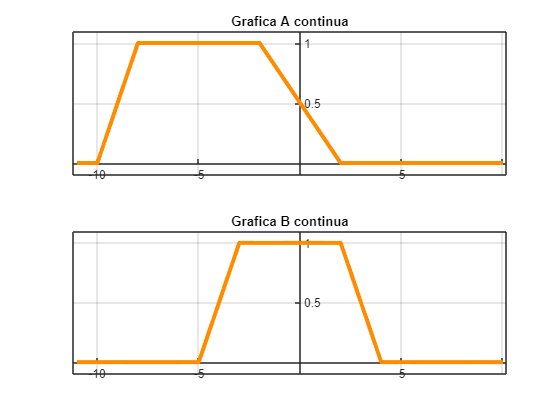

dom = -11:0.1:10;
figure
subplot(2,1,1)
difuzo(dom, [-10 -8 -2 2]);
title('Grafica A continua');
subplot(2,1,2)
difuzo(dom, [-5 -3 2 4]);
title('Grafica B continua');

### Problema 3

Repite el problema anterior pero para conjuntos difusos en tiempo discreto.  

Prueba esta función con los conjuntos difusos (A, B) de la imagen 5 (OperDif5). de las notas *NO2. Operaciones difusas que se encuentran en* la página del curso.

Se espera esta sección dos llamadas a la función con las dos gráficas respectivas. 

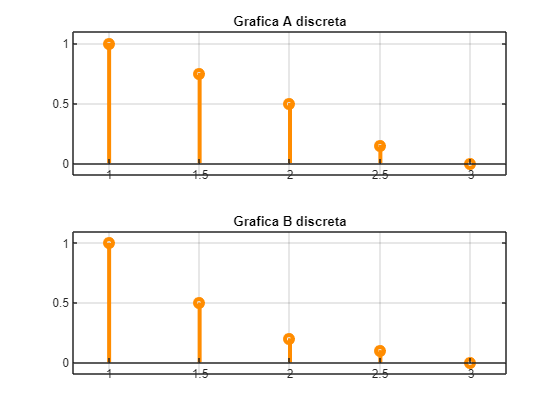

figure
subplot(2,1,1)
difuzod ((1:0.5:3),[1 0.75 0.5 0.15 0]);
title('Grafica A discreta');
subplot(2,1,2)
difuzod((1:0.5:3), [1 0.5 0.2 0.1 0]);
title('Grafica B discreta');

### Problema 4

Elabora una función que reciba el conjunto dominio x y el rango A de un conjunto difuso. Un parámetro adicional que indique el tipo de complemento que se quiere hacer (estándar, Sugeno, Yager). La función debe regresar el rango de valores del conjunto resultante C. Además de imprimir una figura (2 por 1) donde se muestren las grafica de los dos conjunto involucrados.

Prueba esta función con el inciso a) de la imagen 4 (OperDif4). de las notas *NO2. Operaciones difusas que se encuentran en* la página del curso. Para esto:

- Reporta los tres tipos de complementos (si no puedes implentar esto es una solo función crea tres funciones de complemento difuso)

- Combina las herramientas que ya tienes desarrolladas (de ser posible) para mostrar una gráfica con los tres tipos de complementos o desarrolla esta gráfica sin utilizar tus herramientas

En esta sección se espera tres llamadas a la función y un código para generar la cuarta gráfica. 

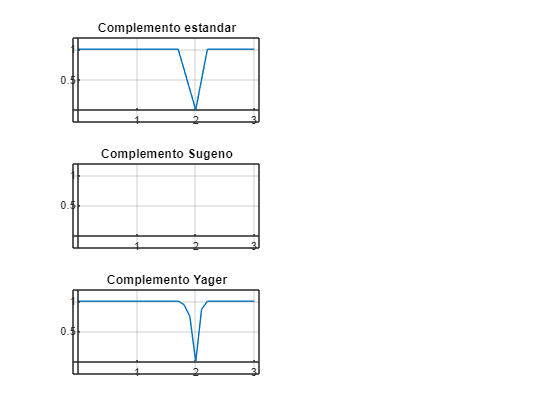

% * Tipo 0= Estandar
% * Tipo 1= Sugeno
% * Tipo 2= Yager
%
% Se propone w = alfa = 2

t = 0:0.1:3;
f1=0;
f2=((t-1.7)/(2-1.7));
f3=((-t+2.2)/(2.2-2));
f4=0;
f=f1.*(t<=1.7)+f2.*(1.7<t&t<=2)+f3.*(2<t&t<=2.2)+f4.*(2.2<t);

figure
subplot(3,2,1)
complemento(t,f,0,0);
title('Complemento estandar');

subplot(3,2,3)
complemento(t,f,1,2);
title('Complemento Sugeno');

subplot(3,2,5)
complemento(t,f,2,2);
title('Complemento Yager');

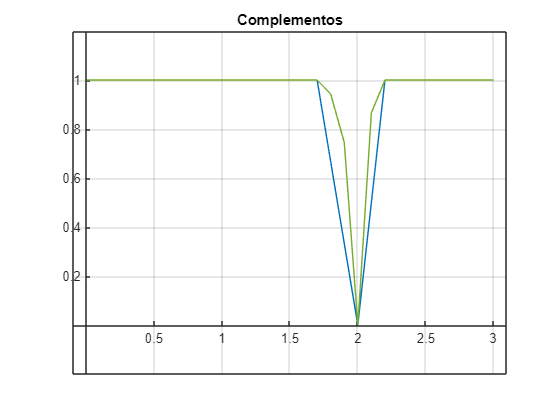

figure
complemento(t,f,0,0);
title('Complementos')
hold on
complemento(t,f,1,2);
complemento(t,f,2,2);
hold off

### Problema 5

Elabora una función que reciba el conjunto dominio x, el rango A, el rango B, de dos conjunto difusos. Un parámetro adicional que indique el tipo de intersección que se quiere hacer (míninimo, producto algebraico, producto acotado). La función debe regresar el rango de valores del conjunto resultante C. Además de imprimir una figura (3 por 1) donde se muestren las grafica de los tres conjunto involucrados.

Prueba esta función con el inciso c) de la imagen 4 (OperDif4). de las notas *NO2. Operaciones difusas que se encuentran en* la página del curso. Para esto:

- Reporta los tres tipos de intersecciones

- Combina las herramientas que ya tienes desarrolladas (de ser posible) para mostrar una gráfica con los tres tipos de intersecciones o desarrolla esta gráfica sin utilizar tus herramientas

En esta sección se espera tres llamadas a la función y un código para generar la cuarta gráfica. 

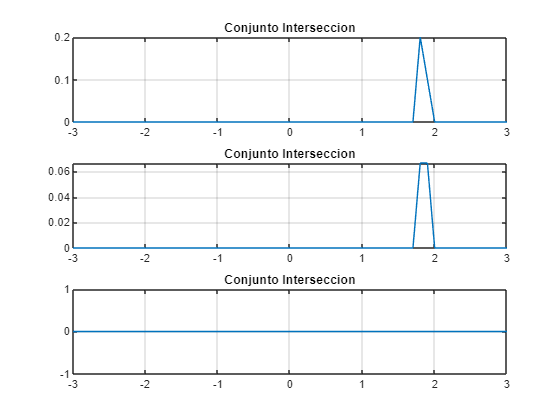

% * Tipo 0= Minimo
% * Tipo 1= Producto algebraico
% * Tipo 2= Producto acotado
%
t = -3:0.1:3;

a=trimf(t,[1.7 2 2.2]);
b=trimf(t,[-2 1 2]);

figure
subplot(3,1,1)
A=interseccion(t,a,b,0);
subplot(3,1,2)
B=interseccion(t,a,b,1);
subplot(3,1,3)
C=interseccion(t,a,b,2);

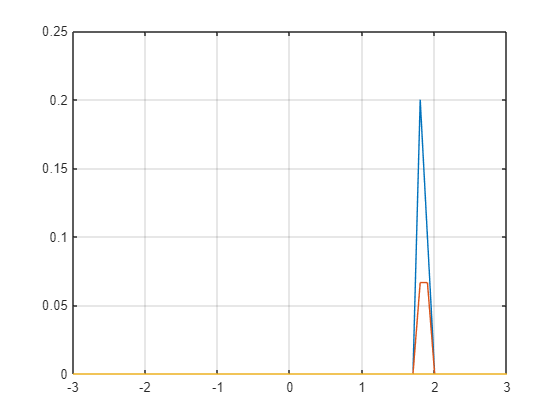

figure
plot(t,A);
grid on
hold on
plot(t,B);
plot(t,C);
hold off

### Problema 6

Elabora una función que reciba el conjunto dominio x, el rango A, el rango B, de dos conjunto difusos. Un parámetro adicional que indique el tipo de unión que se quiere hacer (máximo, suma algebraica, suma acotada). La función debe regresar el rango de valores del conjunto resultante C. Además de imprimir una figura (3 por 1) donde se muestren las grafica de los tres conjunto involucrados.

Prueba esta función con el inciso d) de la imagen 4 (OperDif4). de las notas *NO2. Operaciones difusas que se encuentran en* la página del curso. Para esto:

- Reporta los tres tipos de uniones

- Combina las herramientas que ya tienes desarrolladas (de ser posible) para mostrar una gráfica con los tres tipos de uniones o desarrolla esta gráfica sin utilizar tus herramientas

En esta sección se espera tres llamadas a la función y un código para generar la cuarta gráfica. 

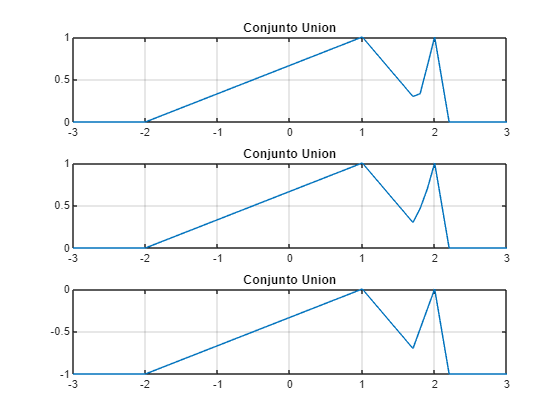

% * Tipo 0= Maximo
% * Tipo 1= Suma algebraica
% * Tipo 2= Suma acotada
%
t = -3:0.1:3;
a=trimf(t,[1.7 2 2.2]);
b=trimf(t,[-2 1 2]);

figure
subplot(3,1,1)
A=union(t,a,b,0);
subplot(3,1,2)
B=union(t,a,b,1);
subplot(3,1,3)
C=union(t,a,b,2);

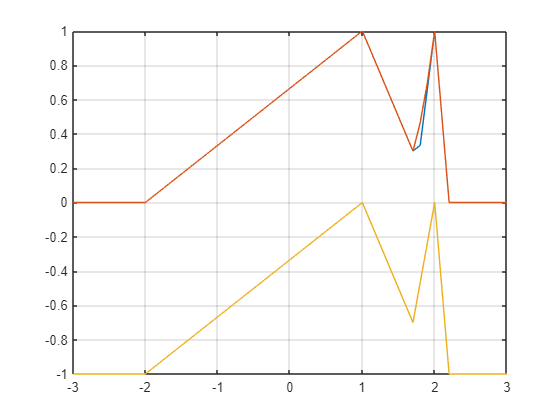

figure
plot(t,A);
grid on
hold on
plot(t,B);
plot(t,C);
hold off

### Problema 7

Resuleve el problema 4 para conjuntos en tiempo discreto. Prueba esta función con el inciso a) de la imagen 5 (OperDif5).

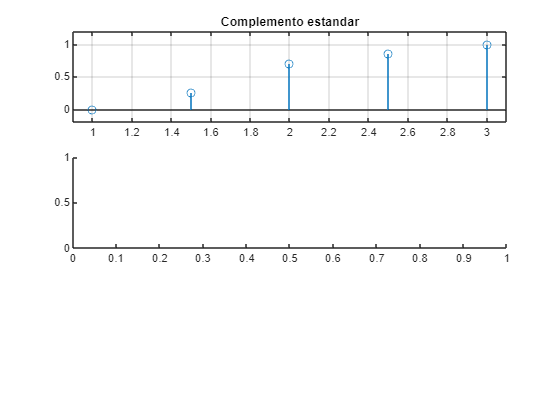

% * Tipo 0= Estandar
% * Tipo 1= Sugeno
% * Tipo 2= Yager
%
% Se propone w = alfa = 2
t = 1:0.5:3;
f=[1 0.75 0.3 0.15 0];

figure
subplot(3,1,1)
a=complementodis(t,f,0,0);
title('Complemento estandar');
subplot(3,1,2)

b=complementodis(t,f,1,2);

Error using stem (line 43)
X must be same length as Y.

Error in P04>complementodis (line 414)
    stem(dominio,rangon);

title('Complemento Sugeno');
subplot(3,1,3)
c=complementodis(t,f,2,2);
title('Complemento Yager');
figure
stem(t,a);
hold on
stem(t,b);
stem(t,c);
hold off

### Problema 8

Resuleve el problema 5 para conjuntos en tiempo discreto. Prueba esta función con el inciso c) de la imagen 5 (OperDif5). 

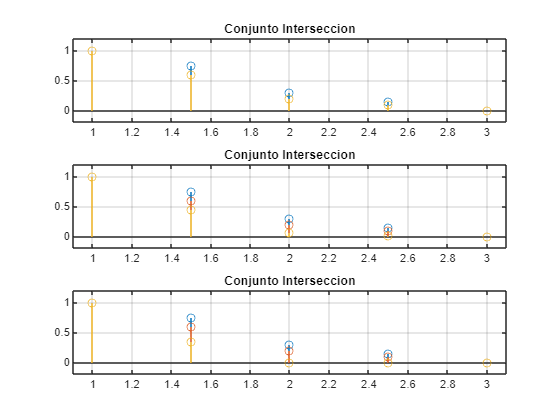

% * Tipo 0= Minimo
% * Tipo 1= Producto algebraico
% * Tipo 2= Producto acotado
%
t = 1:0.5:3;
a=[1 0.75 0.3 0.15 0];
b=[1 0.6 0.2 0.1 0];
figure
subplot(3,1,1)
intersecciondis(t,a,b,0);
subplot(3,1,2)
intersecciondis(t,a,b,1);
subplot(3,1,3)
intersecciondis(t,a,b,2);

### Problema 9

Resuleve el problema 6 para conjuntos en tiempo discreto. Prueba esta función con el inciso d) de la imagen 5 (OperDif5). 

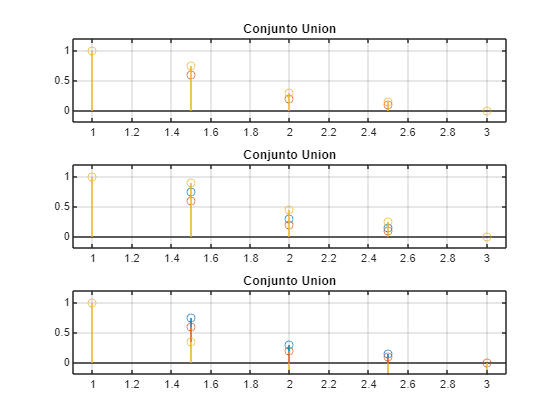

% * Tipo 0= Maximo
% * Tipo 1= Suma algebraica
% * Tipo 2= Suma acotada
%
t = 1:0.5:3;
a=[1 0.75 0.3 0.15 0];
b=[1 0.6 0.2 0.1 0]; 
subplot(3,1,1)
uniondis(t,a,b,0);
subplot(3,1,2)
uniondis(t,a,b,1);
subplot(3,1,3)
uniondis(t,a,b,2);

### Problema 10

Implemente tres funciones,  para calcular las siguientes funciones de membresia

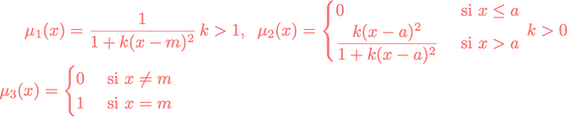

Los párametros que no muestras restricción pueden tener cualquier numero real como argumento, la función debe ser capaz de evaluar vectores de cualquier dimensión. La función $\mu_3
$ recibe el nombre de singleton

Grafique las funciones para los siguintes parámetros (con las herramientas ya construidas)

(a) $$\mu_1(x)\,con \, m=1,\,k=2$, (b) $\mu_1(x)\,con \, m=2,\,k=4$$

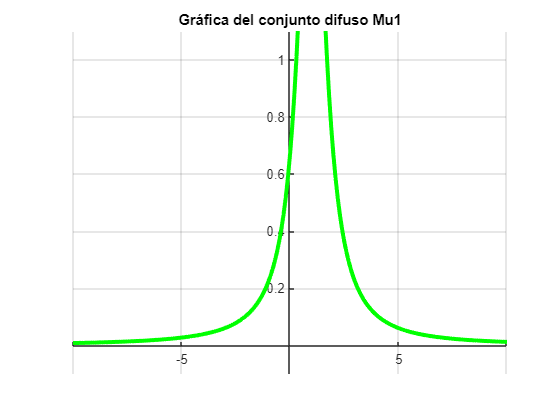

%%Se propuso este dominio
dominium= -10:0.1:10;

%% con m=1, k=2
mu1(dominium,1,2)

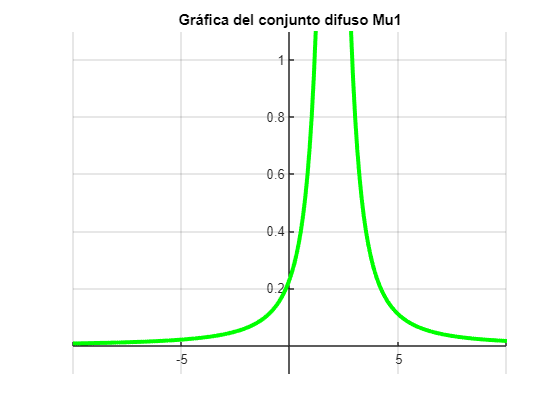

%%con m=2, k=4
mu1(dominium,2,4)


$$(c) \mu_2(x)\,con\, a=1,\,k=2, (d) \mu_2(x)\,con\, a=2\,k=4$$


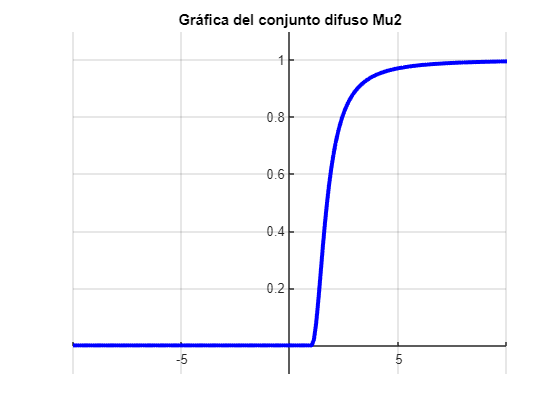

%%con a=1, k=2
mu2(dominium,1,2)

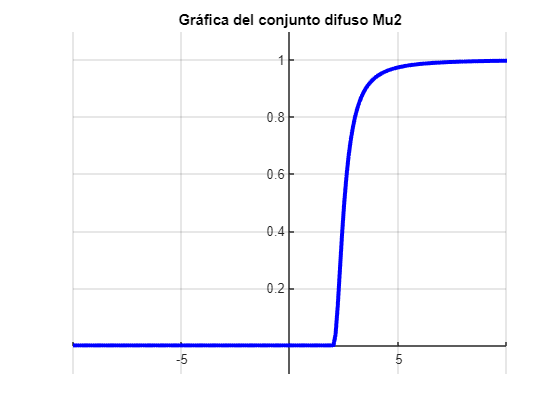

%%con a=2, k=4
mu2(dominium,2,4)


$$(e) \mu_3(x)\,con\, m=2$$


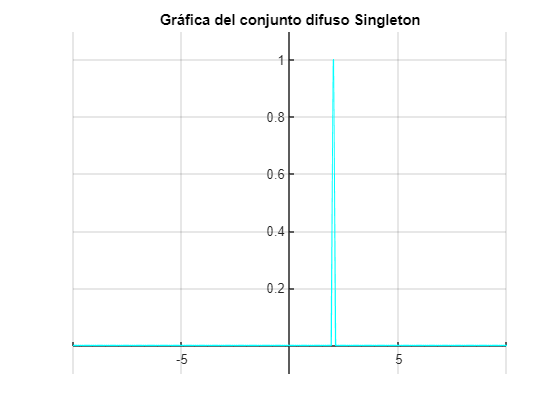

%%con m=2
singleton(dominium,2)

Para ello proponga el dominio x. Se esperan 5 gráficas con el código correspndiente para generarlas.

El código con el el que se crearon las funciones para las prácticas se encontrára en el apartado de **apendices**.

### Problema 11

Implemente una gráfica donde indique ejemplos especificos para ilustrar

 

#### Unión del complemento 

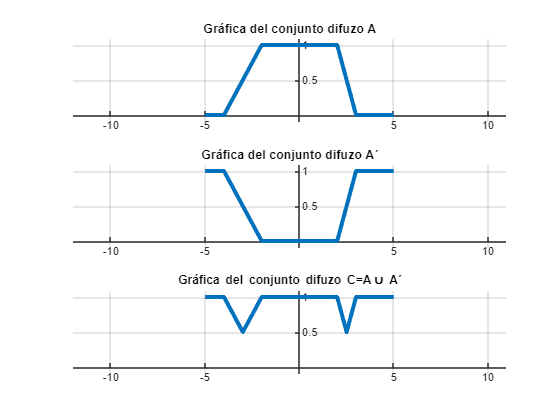

x = -5:0.5:5;
A = trapmf(x,[-4 -2 2 3]);
Ac = 1-A;
C = max(A, Ac);                       % Unión estándar
figure
subplot(3,1,1)
plot(x,A,'LineWidth',3);
grid on
axis([-12,11,-0.1,1.1])
title('Gráfica del conjunto difuzo A')
h = gca;                             % ejes actuales
h.XAxisLocation = "origin";          % eje en el origen
h.YAxisLocation = "origin";          % eje en el origen
h.Box = "off"; 
subplot(3,1,2)
plot(x,Ac,'LineWidth',3);
grid on
axis([-12,11,-0.1,1.1])
title('Gráfica del conjunto difuzo A´')
h = gca;                             % ejes actuales
h.XAxisLocation = "origin";          % eje en el origen
h.YAxisLocation = "origin";          % eje en el origen
h.Box = "off"; 
subplot(3,1,3)
plot(x,C,'LineWidth',3);
grid on
axis([-12,11,-0.1,1.1])
title('Gráfica del conjunto difuzo C=A\cup A´')
h = gca;                             % ejes actuales
h.XAxisLocation = "origin";          % eje en el origen
h.YAxisLocation = "origin";          % eje en el origen
h.Box = "off"; 

#### Intersección del complemento

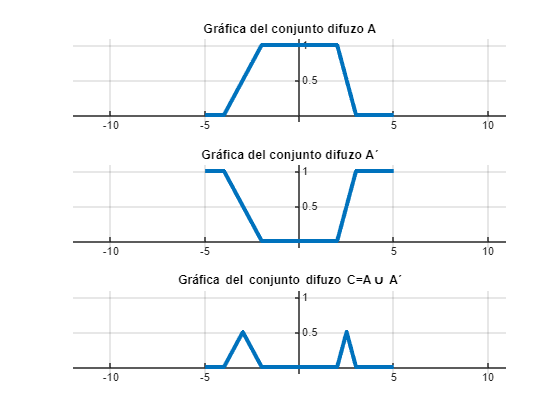


x = -5:0.5:5;
A = trapmf(x,[-4 -2 2 3]);
Ac = 1-A;
C = min(A, Ac);                       % Intersección estándar
figure
subplot(3,1,1)
plot(x,A,'LineWidth',3);
grid on
axis([-12,11,-0.1,1.1])
title('Gráfica del conjunto difuzo A')
h = gca;                             % ejes actuales
h.XAxisLocation = "origin";          % eje en el origen
h.YAxisLocation = "origin";          % eje en el origen
h.Box = "off"; 
subplot(3,1,2)
plot(x,Ac,'LineWidth',3);
grid on
axis([-12,11,-0.1,1.1])
title('Gráfica del conjunto difuzo A´')
h = gca;                             % ejes actuales
h.XAxisLocation = "origin";          % eje en el origen
h.YAxisLocation = "origin";          % eje en el origen
h.Box = "off"; 
subplot(3,1,3)
plot(x,C,'LineWidth',3);
grid on
axis([-12,11,-0.1,1.1])
title('Gráfica del conjunto difuzo C=A\cup A´')
h = gca;                             % ejes actuales
h.XAxisLocation = "origin";          % eje en el origen
h.YAxisLocation = "origin";          % eje en el origen
h.Box = "off"; 

### Problema 12

Escoja tres conjuntos difusos $A,B,C$ con dominuo continuo. La elección debe ser de tal forma que la itersección de B con A y de B con C sea no vacia (esto solo es solo para visulizar la operación, y solo para eso)

 verifique las siguientes propiedades

 

Para la verificación, elabore la gráfica de los conjuntos de cada lado de la igualdad y posteriormente observe que el resultado gráfico es el mismo. 

x = -10:0.1:10;
A = trapmf(x,[-4 -2 2 3]);
B = trapmf(x,[-8 -4 4 6]);
C = trapmf(x,[-9 -5 1 8]); 

#### Primera Propiedad

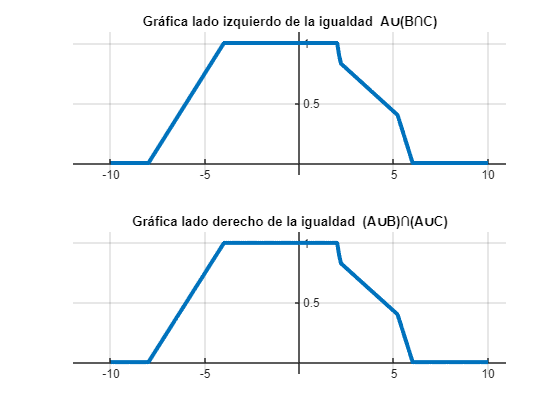


%Lado Izquierdo de la igualdad

BIC= min(B,C) ;              %Intersección estándar entre B y C
AUBIC=max(A,BIC);            %Unión entre A y la intersección de B y C 

%Lado derecho de la igualdad
AUB=max(A,B);               %Unión entre A y B  
AUC=max(A,C);               %Unión entre A y C  
AUBIAUC=min(AUB,AUC); %Intersección entre la unión de A y B y la unión de A y C

%Graficas

figure
subplot(2,1,1)
plot(x,AUBIC,'LineWidth',3);
grid on
axis([-12,11,-0.1,1.1])
title('Gráfica lado izquierdo de la igualdad  A∪(B∩C)')
h = gca;                             % ejes actuales
h.XAxisLocation = "origin";          % eje en el origen
h.YAxisLocation = "origin";          % eje en el origen
h.Box = "off"; 

subplot(2,1,2)
plot(x,AUBIC,'LineWidth',3);
grid on
axis([-12,11,-0.1,1.1])
title('Gráfica lado derecho de la igualdad  (A∪B)∩(A∪C)')
h = gca;                             % ejes actuales
h.XAxisLocation = "origin";          % eje en el origen
h.YAxisLocation = "origin";          % eje en el origen
h.Box = "off"; 

#### Segunda Propiedad

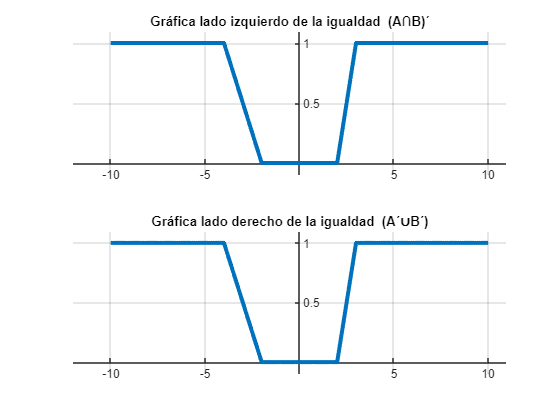


%Lado Izquierdo de la igualdad

AIB= min(A,B);              %Intersección estándar entre A y B
COMAIB=1-AIB;               %Complmento de la Intersección estándar entre A y B 

%Lado derecho de la igualdad
ACOM=1-A;               %Complemento de A  
BCOM=1-B;               %Complemento de B 
ACOMIBCOM=max(ACOM,BCOM); %Unión entre el complemento de A y el complemento de B

%Graficas

figure
subplot(2,1,1)
plot(x,COMAIB,'LineWidth',3);
grid on
axis([-12,11,-0.1,1.1])
title('Gráfica lado izquierdo de la igualdad  (A∩B)´')
h = gca;                             % ejes actuales
h.XAxisLocation = "origin";          % eje en el origen
h.YAxisLocation = "origin";          % eje en el origen
h.Box = "off"; 

subplot(2,1,2)
plot(x,ACOMIBCOM,'LineWidth',3);
grid on
axis([-12,11,-0.1,1.1])
title('Gráfica lado derecho de la igualdad  (A´∪B´)')
h = gca;                             % ejes actuales
h.XAxisLocation = "origin";          % eje en el origen
h.YAxisLocation = "origin";          % eje en el origen
h.Box = "off"; 

#### Tercera Propiedad

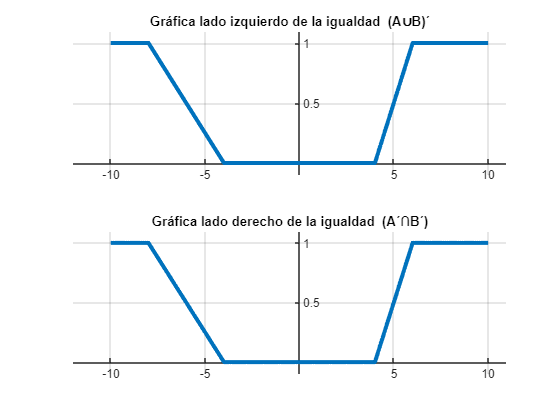


%Lado Izquierdo de la igualdad

AUB= max(A,B);              %Unión estándar entre A y B
COMAUB=1-AUB;               %Complmento de la Intersección estándar entre A y B 

%Lado derecho de la igualdad
ACOM=1-A;               %Complemento de A  
BCOM=1-B;               %Complemento de B 
ACOMIBCOM=min(ACOM,BCOM); %Intersección entre el complemento de A y el complemento de B

%Graficas

figure
subplot(2,1,1)
plot(x,COMAUB,'LineWidth',3);
grid on
axis([-12,11,-0.1,1.1])
title('Gráfica lado izquierdo de la igualdad  (A∪B)´')
h = gca;                             % ejes actuales
h.XAxisLocation = "origin";          % eje en el origen
h.YAxisLocation = "origin";          % eje en el origen
h.Box = "off"; 

subplot(2,1,2)
plot(x,ACOMIBCOM,'LineWidth',3);
grid on
axis([-12,11,-0.1,1.1])
title('Gráfica lado derecho de la igualdad  (A´∩B´)')
h = gca;                             % ejes actuales
h.XAxisLocation = "origin";          % eje en el origen
h.YAxisLocation = "origin";          % eje en el origen
h.Box = "off"; 

## Referencias

- [N/A]. (2020). smf. Help Center. MathWorks®. Recuperado en marzo 2022 de: [https://la.mathworks.com/help/releases/R2020b/fuzzy/smf.html](https://la.mathworks.com/help/releases/R2020b/fuzzy/smf.html)

- [N/A]. (2020). psigmf. Help Center. MathWorks®. Recuperado en marzo 2022 de: [https://la.mathworks.com/help/releases/R2020b/fuzzy/psigmf.html](https://la.mathworks.com/help/releases/R2020b/fuzzy/psigmf.html)

- [http://www.lcc.uma.es/~ppgg/FSS/FSS2.pdf](http://www.lcc.uma.es/~ppgg/FSS/FSS2.pdf)

- [https://sites.google.com/site/logicadifusaingindustrialpaita/logica-difusa/conjuntos-difusos](https://sites.google.com/site/logicadifusaingindustrialpaita/logica-difusa/conjuntos-difusos)

- L. A. Zadeh, “Outline of a New Approach to the Analysis of Complex Systems and Decision Processes," in IEEE Transactions on Systems, Man, and Cyber-netics, vol. SMC-3, no. 1, pp. 28-44.

## Apendices

### Problema 2

function D= difuzo (dominio,rango)
D=trapmf(dominio,rango);
plot(dominio,D,'Color',[1 0.55 0],'LineWidth',3);
grid on
ylim([-0.1 1.1])
aux1x=dominio(1)-0.2;
aux2x=dominio(end)+0.2;
xlim([aux1x aux2x])
h = gca;                             % ejes actuales
h.XAxisLocation = "origin";          % eje en el origen
h.YAxisLocation = "origin";          % eje en el origen
end

### Problema 3

% Problema 3
function D= difuzod (dominio,rango)
D = stem(dominio,rango,'Color',[1 0.55 0],'LineWidth',3);
grid on
ylim([-0.1 1.1])
aux1x=dominio(1)-0.2;
aux2x=dominio(end)+0.2;
xlim([aux1x aux2x])
h = gca;                             % ejes actuales
h.XAxisLocation = "origin";          % eje en el origen
h.YAxisLocation = "origin";          % eje en el origen
end

### Problema 4

function C = complemento(dominio,rango,tipo,alfa)
    if tipo==0
        rangon=1.-rango;
    elseif  tipo==1
        rangon=(1-rango)/(1+alfa.*rango);
    elseif  tipo==2
        rangon=((1.-(rango.^alfa)).^(1/alfa));
    end
    plot(dominio,rangon);
    grid on
    ylim([-0.2 1.2])
    aux1x=dominio(1)-0.1;
    aux2x=dominio(end)+0.1;
    xlim([aux1x aux2x])
    h = gca;                             % ejes actuales
    h.XAxisLocation = "origin";          % eje en el origen
    h.YAxisLocation = "origin";          % eje en el origen
    C=rangon;
end

### Problema 5

function I = interseccion(dominio,rango1,rango2,tipo)
    if tipo==0
        rangoi=min(rango1,rango2);
    elseif  tipo==1
        rangoi=rango1.*rango2;
    elseif  tipo==2
        rangoi=max(0,((rango1+rango2)-1));
    end
    plot(dominio,rango1);
    title('Conjunto A')
    grid on
    plot(dominio,rango2);
    grid on
    title('Conjunto B')
    plot(dominio,rangoi);
    grid on
    title('Conjunto Interseccion')
    I=rangoi;
end

### Problema 6

function U = union(dominio,rango1,rango2,tipo)
    if tipo==0
        rangou=max(rango1,rango2);
    elseif  tipo==1
        rangou=(rango1+rango2)-(rango1.*rango2);
    elseif  tipo==2
        rangou=min(1,((rango1+rango2)-1));
    end
    plot(dominio,rango1);
    title('Conjunto A')
    grid on
    plot(dominio,rango2);
    grid on
    title('Conjunto B')
    plot(dominio,rangou);
    grid on
    title('Conjunto Union')
    U=rangou;
end

### Problema 7

function C = complementodis(dominio,rango,tipo,alfa)
    if tipo==0
        rangon=1.-rango;
    elseif  tipo==1
        rangon=(1.-rango)/(1+(alfa.*rango));
    elseif  tipo==2
        rangon=((1.-(rango.^alfa)).^(1/alfa));
    end
    stem(dominio,rangon);
    grid on
    ylim([-0.2 1.2])
    aux1x=dominio(1)-0.1;
    aux2x=dominio(end)+0.1;
    xlim([aux1x aux2x])
    C=rangon;
end

### Problema 8

function I = intersecciondis(dominio,rango1,rango2,tipo)
    if tipo==0
        rangoi=min(rango1,rango2);
    elseif  tipo==1
        rangoi=rango1.*rango2;
    elseif  tipo==2
        rangoi=max(0,((rango1+rango2)-1));
    end
    stem(dominio,rango1);
    title('Conjunto A')
    grid on
    ylim([-0.2 1.2])
    aux1x=dominio(1)-0.1;
    aux2x=dominio(end)+0.1;
    xlim([aux1x aux2x])
    hold on
    stem(dominio,rango2);
    title('Conjunto B')
    stem(dominio,rangoi);
    title('Conjunto Interseccion')
    hold off
    I=rangoi;
end

### Problema 9

function U = uniondis(dominio,rango1,rango2,tipo)
    if tipo==0
        rangou=max(rango1,rango2);
    elseif  tipo==1
        rangou=(rango1+rango2)-(rango1.*rango2);
    elseif  tipo==2
        rangou=min(1,((rango1+rango2)-1));
    end
    stem(dominio,rango1);
    title('Conjunto A')
    grid on
    ylim([-0.2 1.2])
    aux1x=dominio(1)-0.1;
    aux2x=dominio(end)+0.1;
    xlim([aux1x aux2x])
    hold on
    stem(dominio,rango2);
    title('Conjunto B')
    stem(dominio,rangou);
    title('Conjunto Union')
    hold off
    U=rangou;
end

### Problema 10

Función para mu1.

%Funcion para la ecuacion de mu1
function C=mu1(x,m,k)
if k<1
    disp('Se solicito k>1');
end
mx = (1./(1+k.*(x-m).^2).*k);

figure
plot(x,mx,'g','LineWidth',3);
grid on
axis([-10,10,-0.1,1.1])
title('Gráfica del conjunto difuso Mu1')
h = gca;                             % ejes actuales
h.XAxisLocation = "origin";          % eje en el origen
h.YAxisLocation = "origin";          % eje en el origen
h.Box = "off"; 
end

Función para mu2.

%Funcion para la ecuacion de mu2
function C=mu2(x,a,k)
if k<0
    disp('se solicito k>0')
end
mx = (x<=a).*(0) + (x>a).*((k*(x-a).^2)./(1+k*(x-a).^2));

figure
plot(x,mx,'b','LineWidth',3);
grid on
axis([-10,10,-0.1,1.1])
title('Gráfica del conjunto difuso Mu2')
h = gca;                             % ejes actuales
h.XAxisLocation = "origin";          % eje en el origen
h.YAxisLocation = "origin";          % eje en el origen
h.Box = "off"; 
end

Función para mu3.

%Funcion para la ecuacion de mu3
function [] = singleton(x,m)
singleton = (x~=m).*(0) + (x==m).*(1);

figure
plot(x,singleton,'c','LineWidth',1);
grid on
axis([-10,10,-0.1,1.1])
title('Gráfica del conjunto difuso Singleton')
h = gca;                             % ejes actuales
h.XAxisLocation = "origin";          % eje en el origen
h.YAxisLocation = "origin";          % eje en el origen
h.Box = "off"; 

end